% Opening and Closing
A = imread('opening.JPG')

A = 817×1427×3 uint8 array
A(:,:,1) =

   247   248   250   251   251   250   248   247   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247 

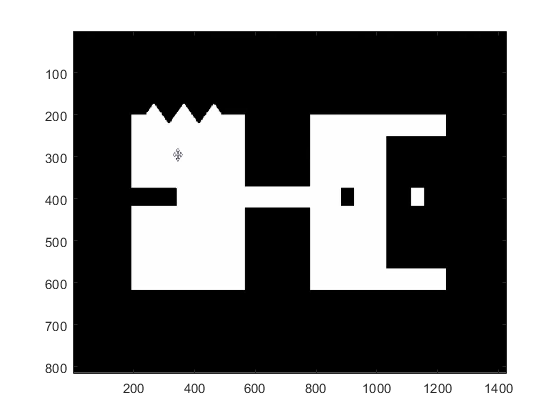

image(A)

## Conversion to Gray Scale

B = rgb2gray(A)

B = 817×1427 uint8 matrix
   247   248   250   251   251   250   248   247   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248
   130   131   133   134   134   133   131   130   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   131   133   133   133   133   133   133   133   133   133   133
    46    47    48    49    49    48    47    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    48    48    48    48    48    48    48    48    48    48
     0     0     0     0     0     0     0     0     0     0     0     

size(B)

ans =          817        1427


 % Defining the Structuring Element
 
 se = strel('square', 55);

## Opening- When erosion is followed by dilation, it's reffered to as Image Opening

Why do we perform these operations?

Because Erosion is going to shrink the object and this deletion will retain it's size again.

A_open = imopen(B, se)

A_open = 817×1427 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

## Closing - Dilation followed by an erosion. So, this isn't going to affect the size of the image. But, we can remove the impurities by using these operations

A_close = imclose(B, se)

A_close = 817×1427 uint8 matrix
   247   248   250   251   251   250   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248
   130   131   133   134   134   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133
    46    47    48    49    49    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48
     3     3     3     3     3     3     3     3     2     2     

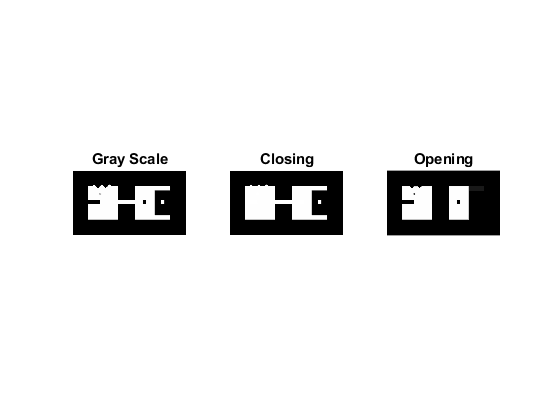

% Plotting
subplot(1,3,1), imshow(B), title('Gray Scale')
subplot(1,3,2), imshow(A_close), title('Closing')
subplot(1,3,3), imshow(A_open), title('Opening')